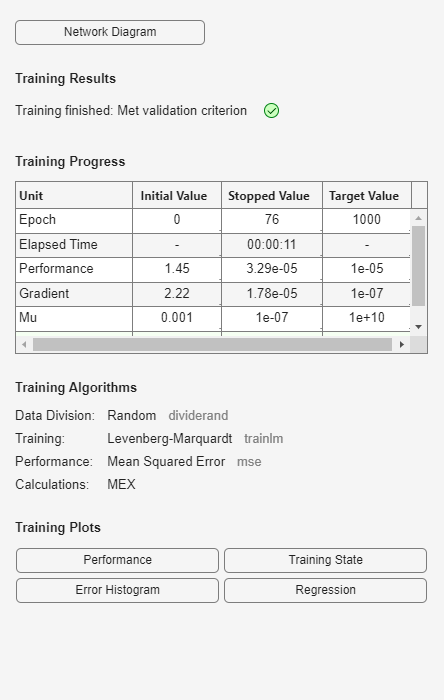

% Load synthetic dataset
data = readtable("C:\Users\vani1\OneDrive\Desktop\eee\synthetic_motor_data.csv", 'VariableNamingRule', 'preserve');


% Extract input features and target output
X = data{:, 1:4}';  % Inputs: [Stator Voltage, Rotor Speed, Load Torque, Slip]
Y = data{:, 5}';    % Output: Speed Response

% Normalize data (optional, but recommended)
X_min = min(X, [], 2);
X_max = max(X, [], 2);
X_norm = (X - X_min) ./ (X_max - X_min); % Min-Max normalization

Y_min = min(Y);
Y_max = max(Y);
Y_norm = (Y - Y_min) / (Y_max - Y_min); % Normalize output

% Split data into training and testing sets (80% train, 20% test)
num_samples = size(X, 2);
train_size = round(0.8 * num_samples);

X_train = X_norm(:, 1:train_size);
Y_train = Y_norm(:, 1:train_size);
X_test = X_norm(:, train_size+1:end);
Y_test = Y_norm(:, train_size+1:end);

% Create and train neural network
hiddenLayerSize = 7; % Number of neurons in hidden layer
net = feedforwardnet(hiddenLayerSize, 'trainlm'); % Use Levenberg-Marquardt

net.trainParam.epochs = 1000; % Maximum training iterations
net.trainParam.goal = 1e-5;   % Training goal (MSE)

% Train the network
net = train(net, X_train, Y_train);

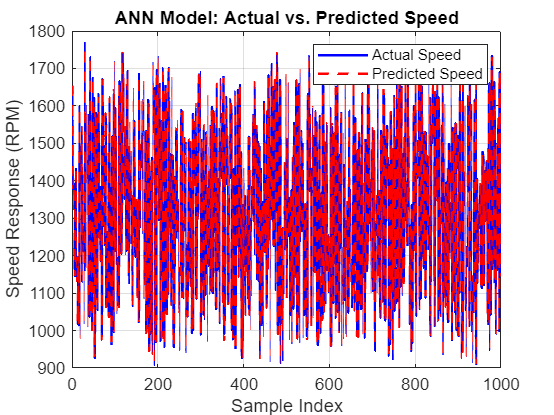


% Test the trained network
Y_pred = net(X_test);

% Convert back to original scale
Y_pred = Y_pred * (Y_max - Y_min) + Y_min;
Y_test = Y_test * (Y_max - Y_min) + Y_min;

% Plot actual vs predicted results
figure;
plot(Y_test, 'b', 'LineWidth', 1.5); hold on;
plot(Y_pred, 'r--', 'LineWidth', 1.5);
legend('Actual Speed', 'Predicted Speed');
xlabel('Sample Index');
ylabel('Speed Response (RPM)');
title('ANN Model: Actual vs. Predicted Speed');
grid on;


% Save trained model
save('trained_ann_model.mat', 'net', 'X_min', 'X_max', 'Y_min', 'Y_max');

disp('Training completed and model saved as trained_ann_model.mat');

Training completed and model saved as trained_ann_model.mat
